# EGM and the political equilibrium

The current version is updated in primo February 2022.

*Clean workspace, layout settings:*

clear;
clc;
close all;
base.layout();

## 1. Settings

 The main model components are collected in a few structs. To allow for more than one model instance (e.g. with different types of policies), we collect these in one layer here.

out = struct();

To initialize a model, we need to at least specify the relevant parameters that we want, what types of policies are in place (e.g. parameters of $\epsilon,\theta$), and what type of population data we might use. The following simply collects a number of default parameter values, and with the input 'E' uses empirical population data from "Inputdata.xlsx":

out.par = SolveF.setup('E'); % with input 'S'.

Add the epsilon/theta values:

out.par.epsilon = 0.475; out.par.theta = 0.824;

Before we calibrate the model, collect the targets:

target = SolveF.target();

The *SolveF *includes the following useful functions:

- *identify_policy(par): *Uses the EGM approach outlined in the paper to identify the period-specific policy functions. Returns a struct with fields *self.h, self.tau, self.tau_m. *This assums that the system is contributive $(\epsilon>0)$. 

- *sim_u(par): *Returns a path for labor supply, PEE taxes, and savings rates (*self.h, self.tau, self.srate *respectively) when pension type is universal $(\epsilon=0$).   

- *sim_c_unique(par): *returns a path for labor supply and PEE taxes (*self.h, self.tau, self.srate *respectively) when pension type is contributve $(\epsilon>0)$. 

- *cal_ss_c(par,target): *Calibrates the model using a steady state approximation; the steady state is approximated using a finite horizon EGM version with constant $\nu_t$. Assumes that $\epsilon>0$.

- *cal_dyn_c(par,target): *Dynamic calibration with the finite horizon EGM. Assumes that $\epsilon>0$

## 2. Baseline calibration and simulation

Our default approach is to use dynamic calibration, assuming the pension system is contributive (and expected to stay this way). This overwrites the existing parameter values with calibrated ones:

out.par = SolveF.cal_dyn_c(out.par,target);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the default value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


Equation solved.

fsolve completed because the vector of function values is near zero
as 

Given the calibrated parameter values, we simulate time path by defining the policy and simulating from it:

[out.sol, out.par] = SolveF.identify_policy(out.par);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the default value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


Equation solved.

fsolve completed because the vector of function values is near zero
as 

out.sim = SolveF.sim_c_unique(out.par,out.sol);

## 3. Counterfactuals:

### 3.1. What happens with universal system, $\epsilon=0$?

Solve with parameter values from before:

out_u = struct();
out_u.par = out.par; out_u.par.epsilon = 0; % copy parameter values, adjust epsilon.
out_u.sim = SolveF.sim_u(out_u.par);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the default value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



### 3.2. Taxes from contributive case, universal economic equilibrium?

TaxC_EEU = SolveF.sim_u_GivenTaxes(out_u.par,out.sim.tau);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the default value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



### 3.3. Taxes from contributive, beveridgean system? 

out_cbev = struct();
out_cbev.par = out.par; out_cbev.par.theta = 0;
[out_cbev.sol, out_cbev.par] = SolveF.identify_policy(out_cbev.par);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the default value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


Equation solved.

fsolve completed because the vector of function values is near zero
as 

out_cbev.sim = SolveF.sim_c_unique(out_cbev.par,out_cbev.sol);

### 3.4: Pure contributive system?

out_c = struct();
out_c.par = out.par; out_c.par.epsilon=1;
[out_c.sol, out_c.par] = SolveF.identify_policy(out_c.par);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the default value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


Equation solved.

fsolve completed because the vector of function values is near zero
as 

out_c.sim = SolveF.sim_c_unique(out_c.par, out_c.sol);

## 4. Results:

### 4.1. Tables

Table with results in 2010 for different systems.

table = struct(); obs = [13,19]; % picks out year 2010, 2040
table.tau = NaN(5,2);
table.tau(1,:) = out.sim.tau(obs); % baseline
table.tau(2,:) = out_u.sim.tau(obs); % universal
table.tau(3,:) = out_c.sim.tau(obs); % epsilon = 1
table.tau(4,:) = out_cbev.sim.tau(obs); % theta = 0
table.tau(5,:) = TaxC_EEU.tau(obs); % taxes from baseline, epsilon = 0 in economic eq.

Labor:�

table.h = NaN(5,2);
table.h(1,:) = out.sim.h(obs); % baseline
table.h(2,:) = out_u.sim.h(obs); % universal
table.h(3,:) = out_c.sim.h(obs); % epsilon = 1
table.h(4,:) = out_cbev.sim.h(obs); % theta = 0
table.h(5,:) = TaxC_EEU.h(obs); % taxes from baseline, epsilon = 0 in economic eq.

Savings:

table.srate = NaN(5,2);
table.srate(1,:) = out.sim.srate(obs-1); % baseline
table.srate(2,:) = out_u.sim.srate(obs-1); % universal
table.srate(3,:) = out_c.sim.srate(obs-1); % epsilon = 1
table.srate(4,:) = out_cbev.sim.srate(obs-1); % theta = 0
table.srate(5,:) = TaxC_EEU.srate(obs-1); % taxes from baseline, epsilon = 0 in economic eq.

### 4.2. Plot paths

Define the main settings (colormaps, font sizes etc.):

psettings = figs.def_psettings(struct());
print = 1; % If 1 print to pdf, if 0 don't.
prefix = 'h0.5_xi0.35'; % Add a prefix to all pdfs.
sim = out.sim; % baseline
sim_u = out_u.sim; % universal
sim_counterfactual = TaxC_EEU; % counterfactual

Print worker-to-retiree ratio:

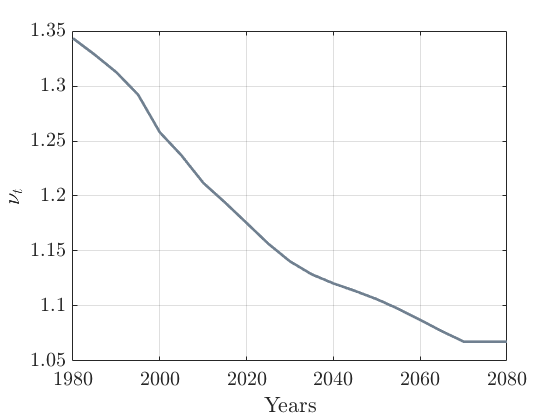

figs.w2r_ratio(out.par.dates,out.par,psettings,print,prefix);

Print tax policy for universal and contributive case:

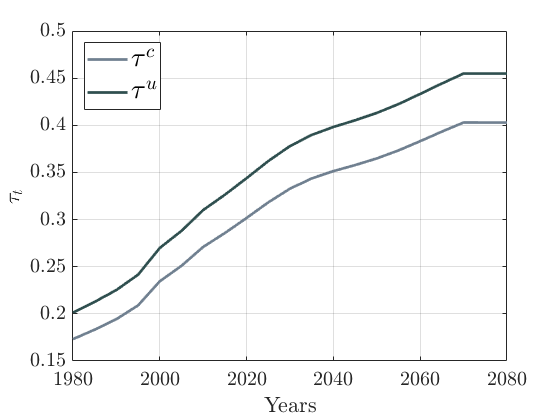

figs.comparetaxes(out.par.dates,psettings,sim,sim_u,print,prefix);

Print savings rates for universal, contributive, and counterfactual (tax = c, behavior = u):

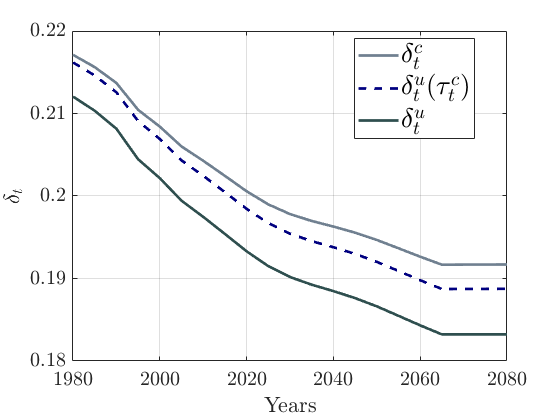

figs.comparesavings(out.par.dates,psettings,sim,sim_u,sim_counterfactual,print,prefix);

Print labor supply for universal, contributive, and counterfactual (tax = c, behavior = u):

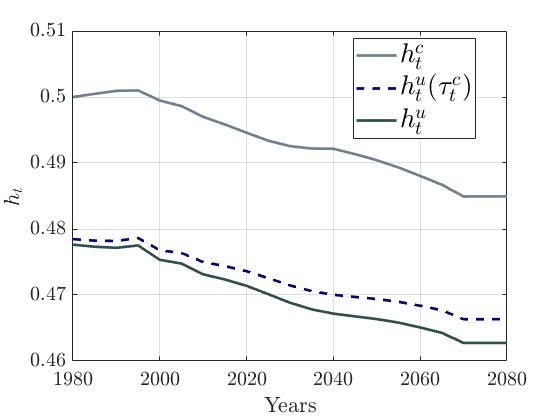

figs.comparelabor(out.par.dates,psettings,sim,sim_u,sim_counterfactual,print,prefix);

### 4.3: Plot the tax in 2010 as a function of epsilon, theta:

Define a grid of [epsilon, theta] values (drop pure universal case for simplicity; this takes a long time with large grids):

epsgrid = linspace(0.01,1,5);
thetagrid = linspace(0,1,5);

For each value on the grid, identify policy function and store h,tau,delta for 2010:

solgrid = struct();
col = 13;
[solgrid.tau, solgrid.h, solgrid.srate] = deal(NaN(length(epsgrid),length(thetagrid)));
par_ij = out.par;
for i=1:length(epsgrid)
    par_ij.epsilon = epsgrid(i);
    for j=1:length(thetagrid)
        par_ij.theta = thetagrid(j);
        [temp_sol, temp_par] = SolveF.identify_policy(par_ij);
        temp_sim = SolveF.sim_c_unique(temp_par,temp_sol);
        solgrid.tau(i,j) = temp_sim.tau(col);
        solgrid.h(i,j) = temp_sim.h(col);
        solgrid.srate(i,j) = temp_sim.srate(col-1);
    end
end


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the default value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


Equation solved.

fsolve completed because the vector of function values is near zero
as 

Plots:

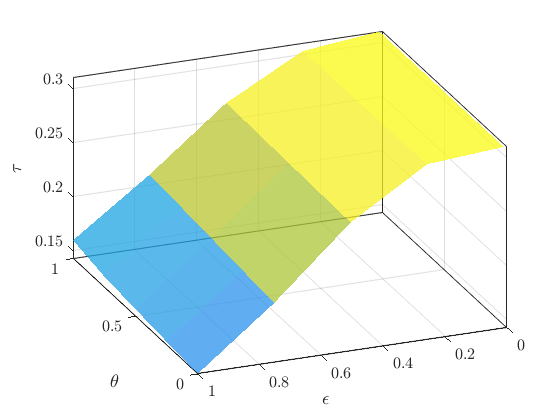

figs.SurfPlot(psettings,epsgrid,thetagrid,solgrid.tau,'tax',print,prefix);

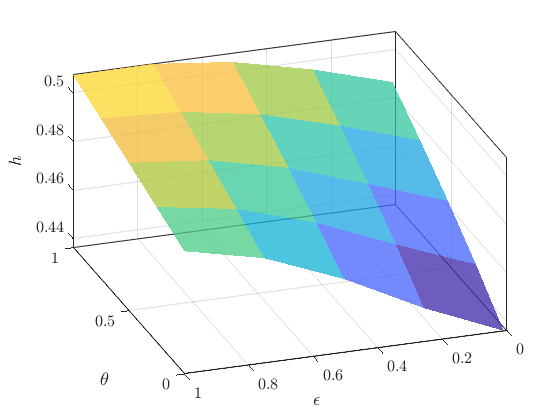

figs.SurfPlot(psettings,epsgrid,thetagrid,solgrid.h,'h',print,prefix);

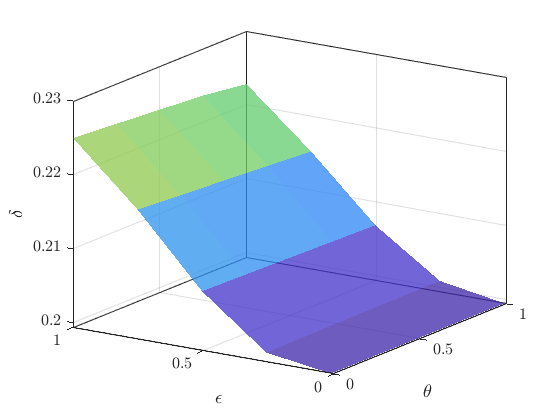

figs.SurfPlot(psettings,epsgrid,thetagrid,solgrid.srate,'srate',print,prefix);